SimulationName='simulation_lifetime_simulationVSexperiment_20220720';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';

cd(savefolder)
mkdir(SimulationName)

filepath=[savefolder SimulationName '/']

Unrecognized function or variable 'savefolder'.

cd(filepath)

spc_openCurves('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_test_lifetime_distribution_20220715/AMAKARPHYS001/AMAKARPHYS001FLIMFLIM030.mat',1)

% Then in the spc_main, do the fitting
% Write down the fitting conditions:
% look up table range 100 200
% the fitting range 1 12
% fix delta peak time No
% fix SHG No

% chi2 3.46
p1_PKA=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_PKA = 0.6920

p2_PKA=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_PKA = 0.3080

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = -0.1066

SHG=spc.fits{1,1}.beta6

SHG = 4.8094e+04

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 1.0165

backcorr=spc.fits{1,1}.backCorr

backcorr = 146.8962


lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     20   246


weight_n_lft=lft_steps(range(1):range(2)).*spc.lifetimes{1}(range(1):range(2));
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_PKA = 3.9003



samplesize_PKA=sum(spc.lifetimes{1})

samplesize_PKA = 2020773

n_exp_PKA=spc.lifetimes{1};

lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;

weight_n_lft=lft_steps(range(1):range(2)).*spc.fits{1,1}.curve';
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.fits{1,1}.curve')

empirical_lft_PKA = 3.8971

tau1_PKA=2.14

tau1_PKA = 2.1400

tau2_PKA=0.69

tau2_PKA = 0.6900

PKA_PopulationName = 'PKA_population_20220720'

% cd(filepath)
% copyfile /Volumes/yaochen/Active/Pingchuan/prf/prf_InsightBottomGreen_20220628.mat prf_PKA.mat
load('prf_PKA.mat')
x=1:1:256;
prf_interp1=interp1(x,prf,x+(delta_peak_time/(12.5/256)),'linear');
prf_interp1(isnan(prf_interp1)) = 0;
prf_peak_PKA=find(prf_interp1==max(prf_interp1))

prf_peak_PKA = 40

find(prf==max(prf))

ans = 38

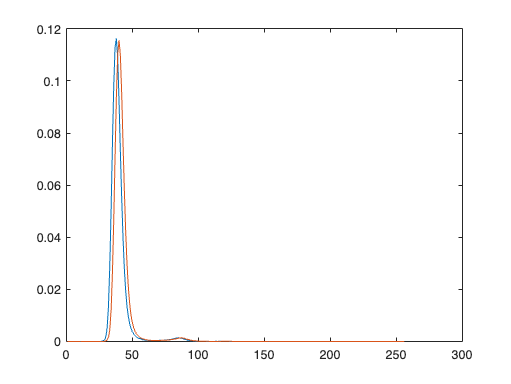

figure
plot(prf)
hold on
plot(prf_interp1)

prf=prf_interp1;
prf_interp1_name='prf_PKA_interp1.mat';
save(prf_interp1_name,'prf')

PKA_PopulationName='PKA_population_20220720'

PKA_PopulationName = 'PKA_population_20220720'

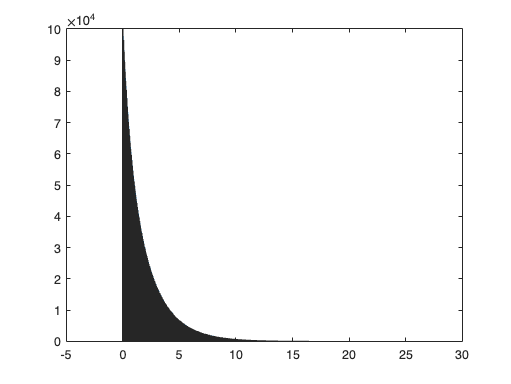

     3511206



GenPop512_Ach(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName,prf_peak_PKA)

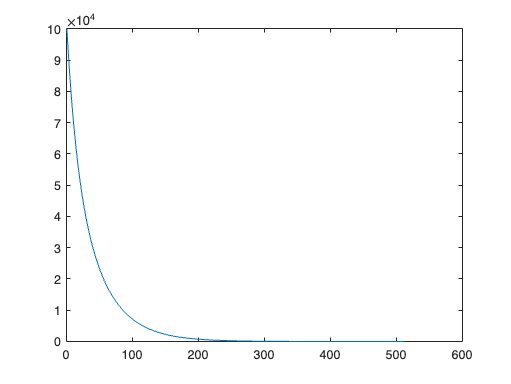

load(PKA_PopulationName)
xsim=linspace(0,25,512);
[n,xout]=hist(Population, xsim);
figure
plot(n)

% SHG_ratio=SHG/samplesize_PKA;
% n(1)=n(1)+SHG_ratio*sum(n);
% hold on
% plot(n)

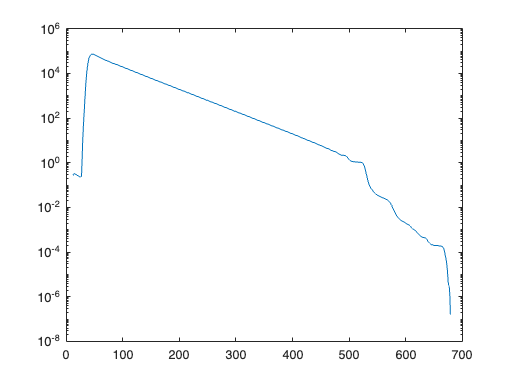

conv_n=conv(n,prf);
figure
semilogy(conv_n)

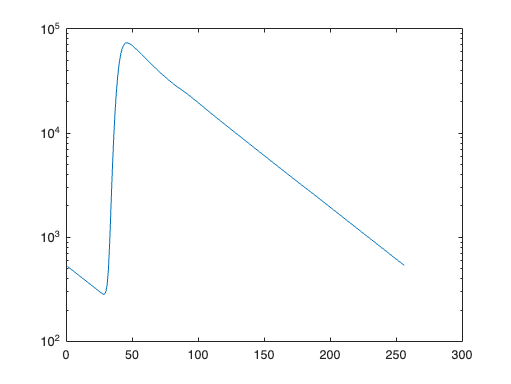


conv_n1=conv_n(257:512);
conv_n_final=conv_n(1:256)+conv_n1;

figure
semilogy(conv_n_final)

lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;

weight_n_lft=lft_steps.*conv_n_final;
empirical_lft_PKA=sum(weight_n_lft)/sum(conv_n_final)

empirical_lft_PKA = 3.8856

backcorr_ratio=backcorr/samplesize_PKA;
backcorr_PKA=sum(conv_n_final)*backcorr_ratio

backcorr_PKA = 255.2389

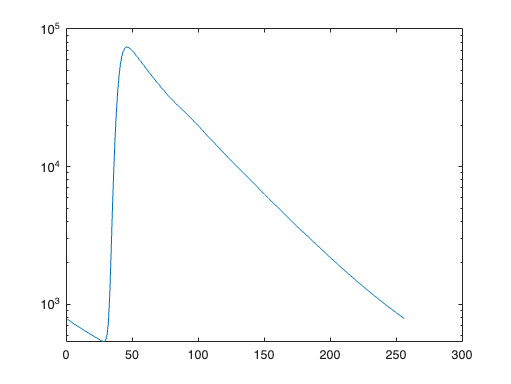

conv_n_final_corr=conv_n_final+backcorr_PKA;
figure
semilogy(conv_n_final_corr)


weight_n_lft=lft_steps(range(1):range(2)).*conv_n_final_corr(range(1):range(2));
empirical_lft_PKA=sum(weight_n_lft)/sum(conv_n_final_corr(range(1):range(2)))

empirical_lft_PKA = 3.9384


% empirical_lft_PKA = 3.9003 histogram
% empirical_lft_PKA = 3.8971 curve

% Then in the spc_main, do the fitting
% Write down the fitting conditions:
% look up table range 100 200
% the fitting range 1 12
% fix delta peak time No
% fix SHG Yes 0

p1_PKA=spc.fits{1,1}.beta1/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p1_PKA = 0.6653

p2_PKA=spc.fits{1,1}.beta3/(spc.fits{1,1}.beta1+spc.fits{1,1}.beta3)

p2_PKA = 0.3347

delta_peak_time=spc.fits{1,1}.beta5

delta_peak_time = -0.0708

SHG=spc.fits{1,1}.beta6

SHG = 0

figureoffset=spc.switchess{1,1}.figOffset

figureoffset = 1.9355

backcorr=spc.fits{1,1}.backCorr

backcorr = 148.1694


lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range=round([spc.fits{1,1}.fitstart spc.fits{1,1}.fitend]/nsPerPoint)

range =     20   246


weight_n_lft=lft_steps(range(1):range(2)).*spc.lifetimes{1}(range(1):range(2));
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.lifetimes{1}(range(1):range(2)))

empirical_lft_PKA = 3.9003


weight_n_lft=lft_steps.*spc.lifetimes{1};
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.lifetimes{1})

empirical_lft_PKA = 3.8978

samplesize_PKA=sum(spc.lifetimes{1})

samplesize_PKA = 2020773

n_exp_PKA=spc.lifetimes{1};

lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;

weight_n_lft=lft_steps(range(1):range(2)).*spc.fits{1,1}.curve';
empirical_lft_PKA=sum(weight_n_lft)/sum(spc.fits{1,1}.curve')

empirical_lft_PKA = 3.8887

load('prf_PKA.mat')
x=1:1:256;
prf_interp1=interp1(x,prf,x+(delta_peak_time/(12.5/256)),'linear');
prf_interp1(isnan(prf_interp1)) = 0;
prf_peak_PKA=find(prf_interp1==max(prf_interp1))

prf_peak_PKA = 39

find(prf==max(prf))

ans = 38


% shows how many channels are shifted

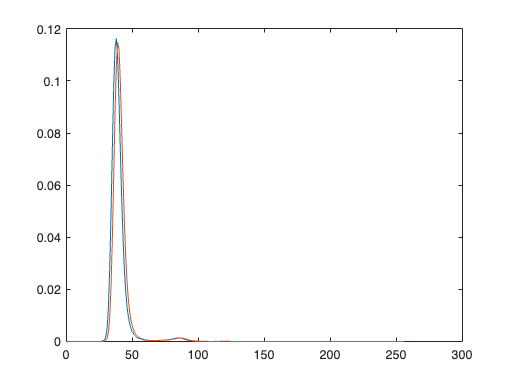

figure
plot(prf)
hold on
plot(prf_interp1)

prf=prf_interp1;
prf_interp1_name='prf_PKA_interp2.mat';
save(prf_interp1_name,'prf')

PKA_PopulationName='PKA_population_20220720_2'

PKA_PopulationName = 'PKA_population_20220720_2'

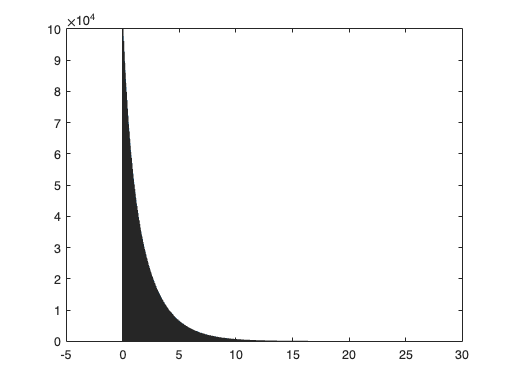

     3432328



GenPop512_Ach(100000,p1_PKA,p2_PKA,tau1_PKA,tau2_PKA,PKA_PopulationName,prf_peak_PKA)

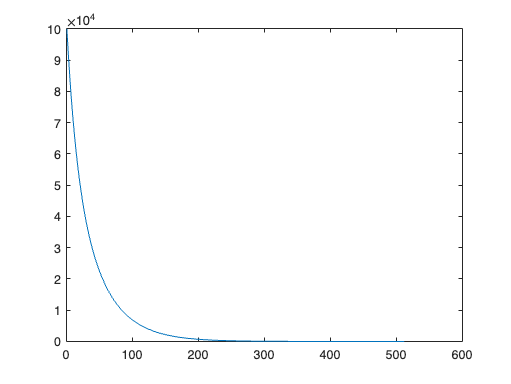

load(PKA_PopulationName)
xsim=linspace(0,25,512);
[n,xout]=hist(Population, xsim);
figure
plot(n)

% SHG_ratio=SHG/samplesize_PKA;
% n(1)=n(1)+SHG_ratio*sum(n);
% hold on
% plot(n)

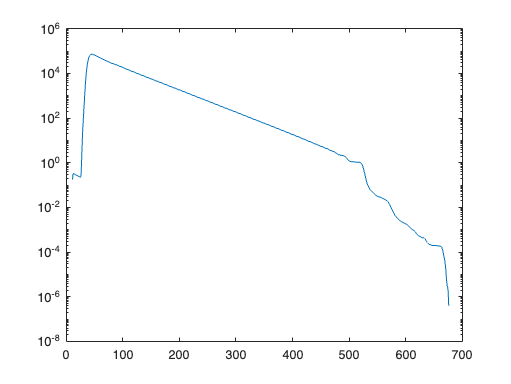

conv_n=conv(n,prf);
figure
semilogy(conv_n)

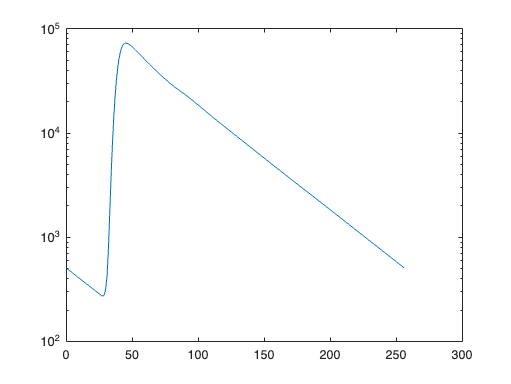


conv_n1=conv_n(257:512);
conv_n_final=conv_n(1:256)+conv_n1;

figure
semilogy(conv_n_final)

lft_steps=(1:1:256)*12.5/256;
lft_steps(1:8)=0;
lft_steps(end-7:end)=0;

weight_n_lft=lft_steps.*conv_n_final;
empirical_lft_PKA=sum(weight_n_lft)/sum(conv_n_final)

empirical_lft_PKA = 3.8324

backcorr_ratio=backcorr/samplesize_PKA;
backcorr_PKA=sum(conv_n_final)*backcorr_ratio

backcorr_PKA = 251.6679

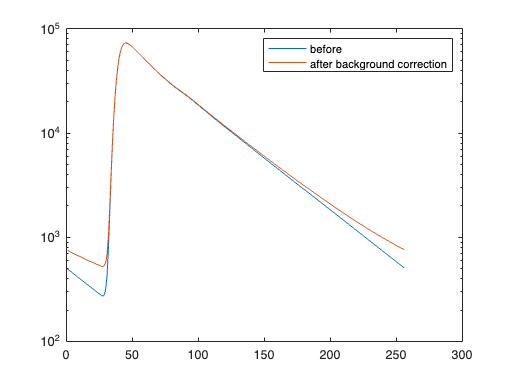

conv_n_final_corr=conv_n_final+backcorr_PKA;
figure
semilogy(conv_n_final)
hold on
semilogy(conv_n_final_corr)
legend('before','after background correction')


weight_n_lft=lft_steps.*conv_n_final_corr;
empirical_lft_PKA=sum(weight_n_lft)/sum(conv_n_final_corr)

empirical_lft_PKA = 3.8702


weight_n_lft=lft_steps(range(1):range(2)).*conv_n_final_corr(range(1):range(2));
empirical_lft_PKA=sum(weight_n_lft)/sum(conv_n_final_corr(range(1):range(2)))

empirical_lft_PKA = 3.8858

copyfile /Volumes/yaochen/Active/Pingchuan/simulation/AutoFluo0917.mat autofluorescence.mat

sum(conv_n_final_corr)

ans = 3.4967e+06

load("autofluorescence.mat")
conv_n_final_corr_auto=conv_n_final_corr+AutoFluo0917*20000

conv_n_final_corr_auto = 1.0e+04 *

    0.0747    0.0736    0.0725    0.0714    0.0704    0.0694    0.0684    0.0674    0.0680    0.0678    0.0655    0.0654    0.0652    0.0629    0.0629    0.0616    0.0608    0.0604    0.0602    0.0588    0.0581    0.0577    0.0570    0.0556    0.0548    0.0542    0.0541    0.0545    0.0558    0.0592    0.0702    0.1068    0.2018    0.4167    0.8104    1.4245    2.2527    3.2330    4.2615    5.2248    6.0305    6.6280    7.0200    7.2370    7.3140    7.2902    7.2015    7.0692    6.9167    6.7481



weight_n_lft=lft_steps(range(1):range(2)).*conv_n_final_corr_auto(range(1):range(2));
empirical_lft_ACh=sum(weight_n_lft)/sum(conv_n_final_corr_auto(range(1):range(2)));

empirical_lft_PKA = 3.8899